### This Code is calculating the DFA coefficcient of the EEG channel 1 as exemple

load Data.mat;

## Extract H components

n=100:20:1000; % Create the different window sizes
N1=length(n);

% Calculate alpha for N2.Cuneus.Epoq20
[channel_cnt, ~] = size(N2.Cuneus.Epoq20);
alpha_file_cuneus = "alpha_data_N2_cuneus.mat";
if ~isfile(alpha_file_cuneus)
    all_alpha_cuneus = zeros(1, channel_cnt); % Preallocate all_alpha
    for channel = 1:channel_cnt 
        alpha = do_dfa(N2.Cuneus.Epoq20(channel, :), n, 1);
        disp(['Processing Cuneus channel ', num2str(channel), '...']);
        all_alpha_cuneus(channel) = alpha(1);
        disp(["Alpha1 for Cuneus channel ", num2str(channel), "= ", alpha(1)]);
    end
    save(alpha_file_cuneus, "all_alpha_cuneus");
else
    disp("Alpha data for Cuneus already exists. Skipping calculation.");
    load(alpha_file_cuneus, "all_alpha_cuneus");
end

Alpha data for Cuneus already exists. Skipping calculation.



% Calculate alpha for N2.Ocipit.Epoq20
[channel_cnt, ~] = size(N2.Ocipit.Epoq20);
alpha_file_ocipit = "alpha_data_N2_ocipit.mat";
if ~isfile(alpha_file_ocipit)
    all_alpha_ocipit = zeros(1, channel_cnt); % Preallocate all_alpha
    for channel = 1:channel_cnt 
        alpha = do_dfa(N2.Ocipit.Epoq20(channel, :), n, 1);
        disp(['Processing Ocipit channel ', num2str(channel), '...']);
        all_alpha_ocipit(channel) = alpha(1);
        disp(["Alpha1 for Ocipit channel ", num2str(channel), "= ", alpha(1)]);
    end
    save(alpha_file_ocipit, "all_alpha_ocipit");
else
    disp("Alpha data for Ocipit already exists. Skipping calculation.");
    load(alpha_file_ocipit, "all_alpha_ocipit");
end

Alpha data for Ocipit already exists. Skipping calculation.


% Print mean alpha for both region
mean_ocipit = mean(all_alpha_ocipit)

mean_ocipit = 0.6030

mean_cuneus = mean(all_alpha_cuneus)

mean_cuneus = 0.6273

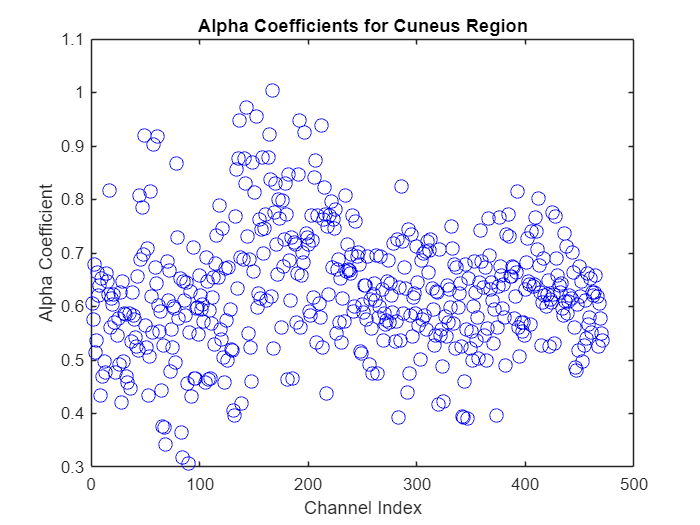

% Show coefficient distribution
% Plot point graph for Cuneus region
figure;
plot(1:numel(all_alpha_cuneus), all_alpha_cuneus, 'bo', 'MarkerSize', 8);
xlabel('Channel Index');
ylabel('Alpha Coefficient');
title('Alpha Coefficients for Cuneus Region');

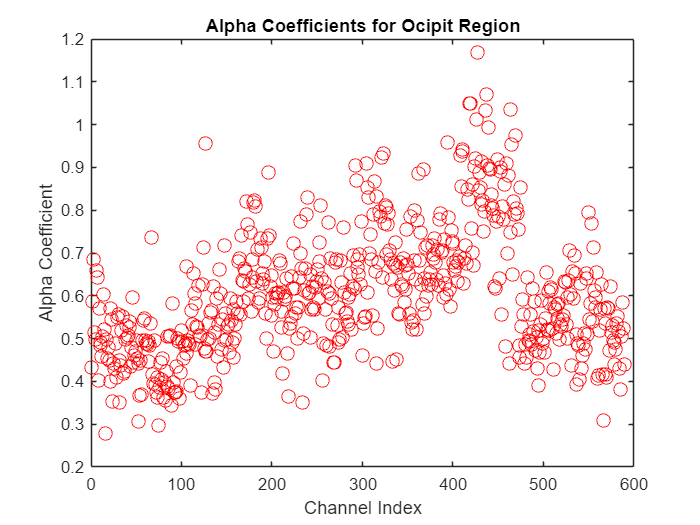


% Plot point graph for Ocipit region
figure;
plot(1:numel(all_alpha_ocipit), all_alpha_ocipit, 'ro', 'MarkerSize', 8);
xlabel('Channel Index');
ylabel('Alpha Coefficient');
title('Alpha Coefficients for Ocipit Region');

% data for the box plot
data_boxplot = {all_alpha_cuneus,all_alpha_ocipit};

% create the box plot
boxplot([all_alpha_cuneus,all_alpha_ocipit]);
title('Box Plot of Alpha Coefficients for Cuneus and Ocipit Regions');
xlabel('Brain Regions');
ylabel('Alpha Coefficient');


Error using boxplot>straightenX
'X' parameter must be a numeric vector or matrix.

Error in boxplot (line 275)
[xDat,gDat,origRow,xlen,gexplicit,origInd,origNumXCols] = straightenX(x,g);

% Print signal in interesting area
figure
hold on
plot(N2.Ocipit.Epoq20(393,:));
plot(N2.Cuneus.Epoq20(463,:));

## Wavelet

### Apply wavelet transform

signal = N2.Cuneus.Epoq20(450,:)
alpha_signal_before = do_dfa(signal, n, 1);
% La longueur du signal doit etre une puisscance de 2
% on fait du zero-padding
M1 = length(signal);     
M2 = 2^nextpow2(M1);    
ofs = round((M2-M1)/2);
s = zeros(1,M2);
t = zeros(1,M2);
% Signal dyadique:
s(ofs:ofs+M1-1) = signal;

% Visualisation:
f1 = figure('Position',[100 100 1300 700]);
subplot(4,6,[1 1 6]); plot(signal)
set(gca,'fontsize',14,'Color','none')
ylabel('mV')
title('signal initial')

% % Choose a fractional spline wavelet transform
alpha=2.4;          % Real value larger than -0.5
tau=0.3;            % Real value between -0.5 and +0.5
type='ortho';       % Options are:  1. 'bspline'
                    %               2. 'ortho'
                    %               3. 'dual'
% Plot of the synthesis scaling function and the wavelet
[x,y1]=fractsplinefunction(alpha,tau,type,10);
[x,y2]=fractsplinewaveletfunction(alpha,tau,type,10);

% Transformee en ondelettes spline                   
[FFTanalysisfilters,FFTsynthesisfilters] = FFTfractsplinefilters(M2,alpha,tau,type);

% Perform a fractional spline wavelet transform of the signal
J = 8;                % Number of decomposition levels
w = FFTwaveletanalysis1D(s,FFTanalysisfilters,J);

% Show the whole wavelet transform
subplot(4 ,6,[13 18 19 20]),waveletplot1D(w,J)
xlim([1 4096])
set(gca,'fontsize',14)
title({['Trans. en ondelettes Spline-Fract. (' num2str(J) ' niveaux)']})

## Perform Shrinkage

figure;
% original signal
subplot(2,1, 1); plot(signal)
set(gca,'fontsize',14,'Color','none')
ylabel('mV')
title('signal initial')

% Perform thresholding (shrinkage)
threshold = 100; % Set your threshold value
shrinked_w = wthresh(w, 's', threshold);
% Reconstruction of the signal from its tresholded wavelet transform coef
s0_shrink = FFTwaveletsynthesis1D(shrinked_w,FFTsynthesisfilters,J);
signal0_schrink = s0_shrink(ofs:ofs+M1-1);
alpha_signal_shrinked = do_dfa(signal0_schrink, n, 1);

% Plot
subplot(2,1, 2); plot(signal0_schrink)
set(gca,'fontsize',14,'Color','none')
ylabel('mV')
title('Signal reconstruct with shrink coef')

alpha_signal_shrinked
alpha_signal_before

## Reconstruct from one subband : 4

figure
% Reconstruction from only one subband: use of the second output parameter
% from the function wextract1D.m
bandnumber = 4;       
[b0,w0] = wextract1D(w,J,bandnumber);
s1 = FFTwaveletsynthesis1D(w0,FFTsynthesisfilters,J);
signal1 = s1(ofs:ofs+M1-1);

subplot(2,1,[2 1]); plot(signal1)
titletext=['Signal rereconstruit a partir des coeff. en ondelettes de profondeur ' num2str(bandnumber)];
set(gca,'fontsize',14,'Color','none')
xlabel('temps'); ylabel('mV')
title(titletext)



### Perform shrinkage